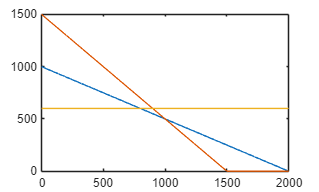

% Matrice for given inequilities/equations
C = [3 5];
A = [1 2; 1 1; 0 1];
b = [2000; 1500; 600];
% for the plotting
y1 = 0 : 1 : max(b);

% x = (b - A( , 1) *y1 ) / A( , 2)
x21 = (b(1) - A(1,1) .* y1) ./ A(1, 2);
x22 = (b(2) - A(2,1) .* y1) ./ A(2, 2);
x23 = (b(3) - A(3,1) .* y1) ./ A(3, 2);

% why max?
x21=max(0,x21);
x22=max(0,x22);
x23=max(0,x23);

plot(y1, x21, y1, x22, y1, x23);

cx1 = find(y1 == 0);
c1 = find(x21 ==0); % intersection on x axis
line1 = [y1(:,[c1 cx1]); x21(:,[c1 cx1])]';

c2 = find(x22 ==0);
line2 = [y1(:,[c2 cx1]); x22(:,[c2 cx1])]';

c3 = find(x23 ==0);
line3 = [y1(:,[c3 cx1]); x23(:,[c3 cx1])]';

corpt = unique([line1; line2; line3],'rows');

% find poits of intersection
HG = [0;0];
for i = 1:size(A,1)
    hg1 = A(i,:);
    b1 = b(i,:);
    for j = i+1 : size(A,1)
        hg2 = A(j,:);
        b2 = b(j,:);
        Aa = [hg1; hg2];
        Bb = [b1; b2];
        Xx = Aa\Bb;
        HG = [HG Xx];
    end
end

pt = HG';

allpt = [pt; corpt];
points = unique(allpt,'rows')

points =            0           0
           0         600
           0        1000
           0        1500
         800         600
         900         600
        1000         500
        1500           0
        1501           0
        1502           0
        1503           0
        1504           0
        1505           0
        1506           0
        1507           0
